# Taller 2

clear


## Propiedades del motor

Kt = 1.57e-2*1;Ke = Kt;
Ra = 8*1;
B = 2.52e-3*1;
J = 9.85e-3*1;
m=0.3*1;
d=0.05*1;
g=9.81;

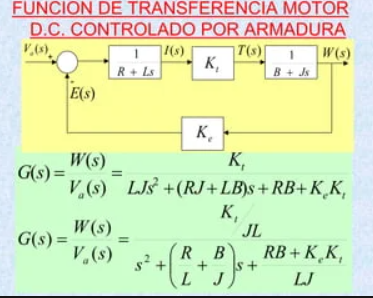

### Definición inductancia

s=tf('s');
PoloSM=pole(1/(B+J*s))

PoloSM = -0.2558

#### Inductancia infinitamente pequeña

%L=5e-5
%PoloSE=pole(1/(Ra+L*s))
%gan=1.236e-1 %Pse<<Psm
%Go=gan/(L+Ra*gan)

#### Inductancia "pequeña"

L=Ra/(B/J*10)

L = 3.1270

PoloSE=pole(1/(Ra+L*s))

PoloSE = -2.5584

gan=45  %Pe=-5Pm

gan = 45

### Sistema eléctrico Simplificado

Go=gan/(L+Ra*gan)

Go = 0.1239

Go=0.125

Go = 0.1250

### Sistema Pol grado 5

Gp=Go*Kt*(1/(J*s)/(1+B/(J*s)));
Gpo=Gp/(1+Gp*Ke)

Gpo =
 
          1.876e-09 s^3 + 4.798e-10 s^2
  ---------------------------------------------
  9.413e-09 s^4 + 4.846e-09 s^3 + 6.237e-10 s^2
 
Continuous-time transfer function.



### Sistema Pol grado 3

Num=Gpo.Numerator{1}(1:3)

Num = 	1.0e+-8 *

         0    0.1876    0.0480


Den=Gpo.Denominator{1}(1:3)

Den = 	1.0e+-8 *

    0.9413    0.4846    0.0624


## Controlador

delta=0*(pi/180);
cond_init=0*(pi/180);

a=2;
beta=12;

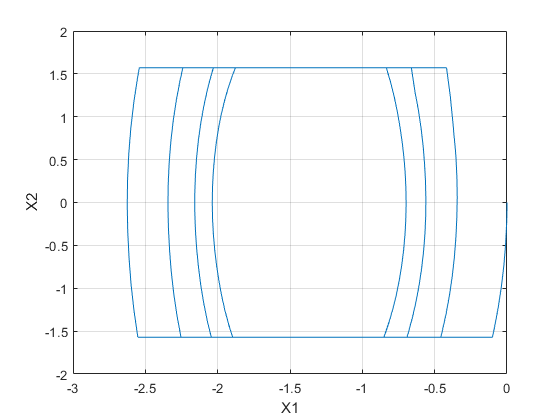



sim("SMCsimplificado.slx");
simout=ans;


figure(1)
plot(simout.X.Data(:,3),simout.X.Data(:,2))
grid on
xlabel("X1")
ylabel("X2")

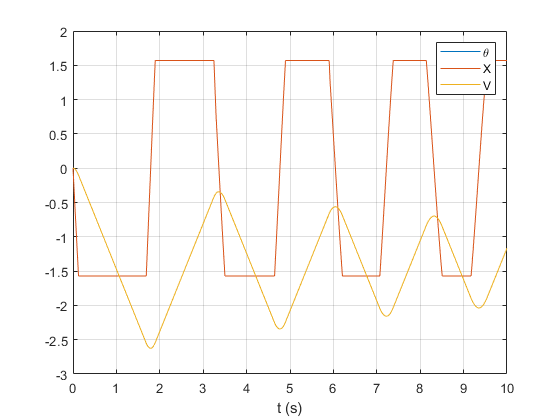


figure(2)
plot(simout.X.Time,simout.X.Data)
legend("\theta","X","V")
xlabel("t (s)")
grid on

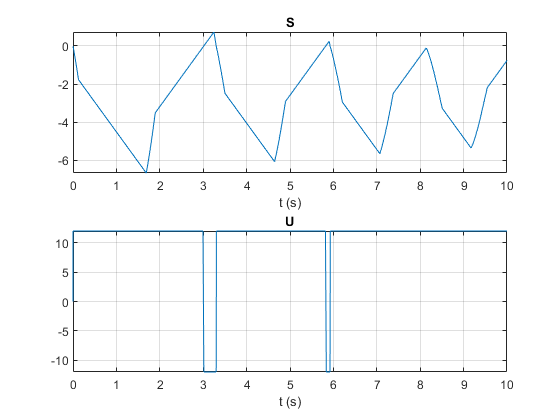


figure(3)
subplot(2,1,1)
plot(simout.S.Time,simout.S.Data)
title("S")
xlabel("t (s)")
grid on
subplot(2,1,2)
plot(simout.U.Time,simout.U.Data)
title("U")
xlabel("t (s)")
grid on

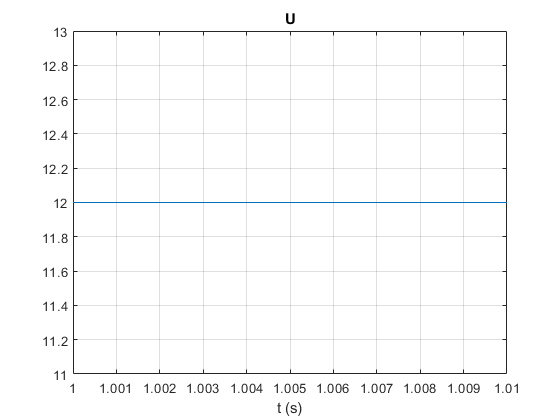


figure()
plot(simout.U.Time,simout.U.Data)
title("U")
xlabel("t (s)")
xlim([1 1.01])
grid on


t=simout.U.Time(1:(end-1))

t =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


x=simout.U.Data(1:(end-1))

x =      0
    12
    12
    12
    12
    12
    12
    12
    12
    12


L=length(t)

L = 200000

Y=fft(x,L)

Y = 	1.0e+05 *

   8.0347 + 0.0000i
  -1.0133 + 0.6871i
   0.4566 + 1.2493i
  -0.1555 + 0.4680i
   0.3088 + 0.1640i
  -0.0057 + 0.3988i
   0.0638 + 0.2069i
   0.1133 + 0.1312i
   0.4294 + 0.4876i
   0.0088 - 0.3192i


T=t(2)-t(1)

T = 5.0000e-05

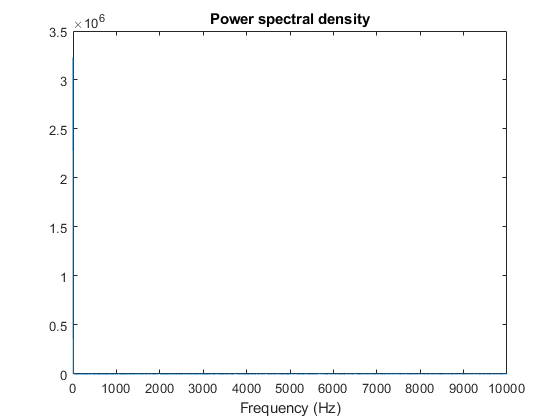


Fs=T^-1;

Pyy = Y.*conj(Y)/L;
f = Fs*(0:(L/2))/L;
P1 = Pyy(1:L/2+1);
plot(f,P1)
title('Power spectral density')
xlabel('Frequency (Hz)')

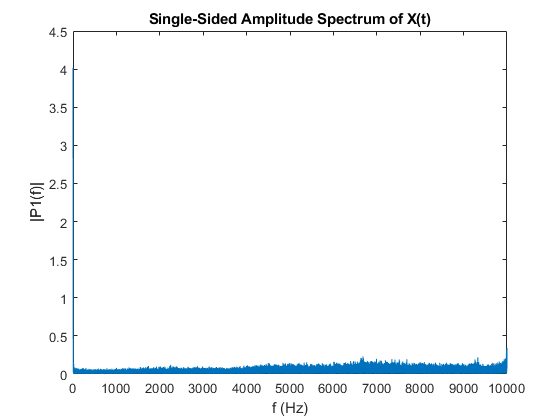


P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);


figure()
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')
xlim([0 10000])


[pks,locs] = findpeaks(x);
periods = diff(locs) / Fs;
freq = 1 / mean(periods)

freq = 5.8419e+03